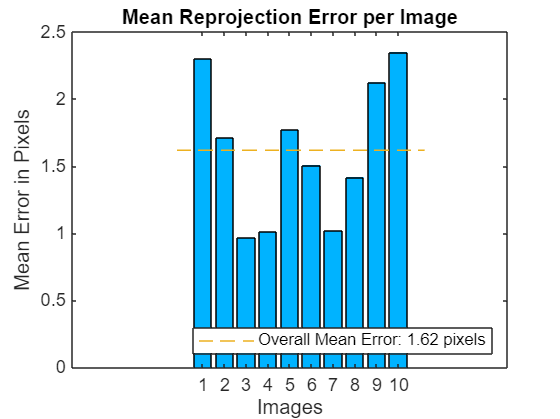

% Auto-generated by cameraCalibrator app on 26-Jul-2025
%-------------------------------------------------------


% Define images to process
imageFileNames = {'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal1_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal2_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal4_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal5_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal6_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal10_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal12_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal13_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal14_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\Proyecto\fotos_cam_segmentadas\cal18_seg.png',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
minCornerMetric = 0.120000;
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames, 'MinCornerMetric', minCornerMetric, 'HighDistortion', true);
imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25.000000;  % in millimeters
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

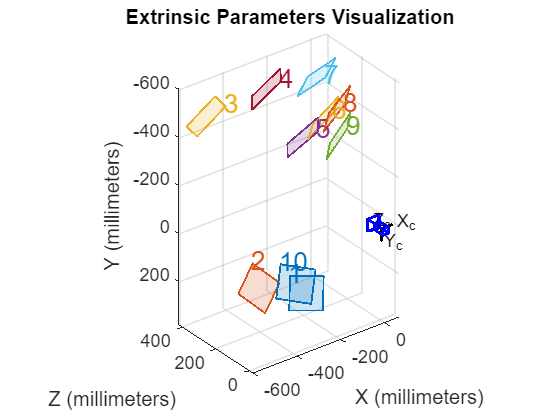


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  297.3269 +/- 16.0296     255.4519 +/- 14.5298 ]
Principal point (pixels):[  621.4361 +/- 8.9478      572.8847 +/- 2.2970  ]
Radial distortion:       [   -0.1195 +/- 0.0133        0.0092 +/- 0.0021  ]
Tangential distortion:   [    0.0017 +/- 0.0009        0.0028 +/- 0.0012  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.3945 +/- 0.0368        0.0384 +/- 0.0175        0.3082 +/- 0.0141  ]
                         [   -0.3130 +/- 0.0296        0.0474 +/- 0.0190        0.8102 +/- 0.0118  ]
                         [    0.0091 +/- 0.0303       -0.4563 +/- 0.0396        2.4032 +/- 0.0136  ]
                         [   -0.1893 +/- 0.0372       -0.6560 +/- 0.0504        2.5986 +/- 0.0204  ]
                         [   -0.1204 +/- 0.0284       -0.6634 +/- 0.0429        2.6428 +/- 0.0152  ]
                         [


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')
